% The steps of the project

% 1. Face Detection: Use face detection algorithms to find the face within the image.
% 2. Feature Detection: Apply feature detection algorithms to locate the eyes and mouth.
% 3. Geometric Transformation: Apply transformations to rotate, scale, and translate the image so that the eyes (and if possible, the mouth) are aligned to a standard template.
% 4. Cropping and Resizing: Crop the aligned face to a standard size and resize it if necessary.
% 5. PCA and Eigenface Generation: Once the images are normalized and aligned, proceed with PCA and eigenface generation as you've already done.
% 6. Recognition: When a new image is received, apply the same preprocessing steps to it before projecting it onto the eigenface space for recognition.

addpath('functions');

% Main-file
% img1 = imread("images/DB1/db1_01.jpg");
% img2 = imread("images/DB1/db1_02.jpg");
% img3 = imread("images/DB1/db1_03.jpg");

% PART 1 (purpose to find eyes)

% Load dataset

% Skin detection? (DB2)

% Illuminant compensation

% White balance

% Image color correction?

% Convert to YCbCR (combine with HSV?)

% Face mask

% Detect face

% % ginput, BOB lab 1. Level slicing

% Eye map: Chrominance & Luminance

% Mouth map?

% Eye mask + face mask (grade 5)

% Normilization

% 1. Color Space Conversion:
% Faces generally have a distinct color range that can be 
% more easily separated in color spaces like YCbCr or HSV 
% rather than RGB.

% 2. Skin Color Segmentation:
% Identify the range of skin tones in the chosen color space 
% and create a binary mask that includes these tones while 
% excluding others.

% 3. Morphological Operations:
% Use operations like erosion and dilation to clean up the 
% binary mask. This can help to remove noise and fill in gaps.

% 4. Connected Component Analysis:
% Identify connected regions in the binary mask and filter out 
% regions based on size, shape, or other criteria to isolate 
% the face.

% 5. Feature-Based Segmentation:
% Use edge detection filters like Sobel or Canny to find 
% boundaries, and then use these edges to help segment 
% the face.

% 6. Refinement of Mask:
% Further refine the mask to the face's exact shape using 
% morphological operations or by combining the mask with 
% edge information.

% 7. Lighting and Contrast:
% Handle variations in lighting and contrast to ensure that 
% the skin segmentation is as accurate as possible.

% 8. False Positives and Negatives:
% Develop strategies to reduce false positives (non-face 
% regions detected as face) and false negatives (face regions 
% not detected).

% 9. Iterative Approach:
% Often, a single pass is not enough. An iterative approach, 
% where you refine the mask multiple times, can yield better 
% results.

% 10. Domain Knowledge:
% Incorporating knowledge about facial features can be very 
% helpful, like the approximate location and size of a face 
% in an image.

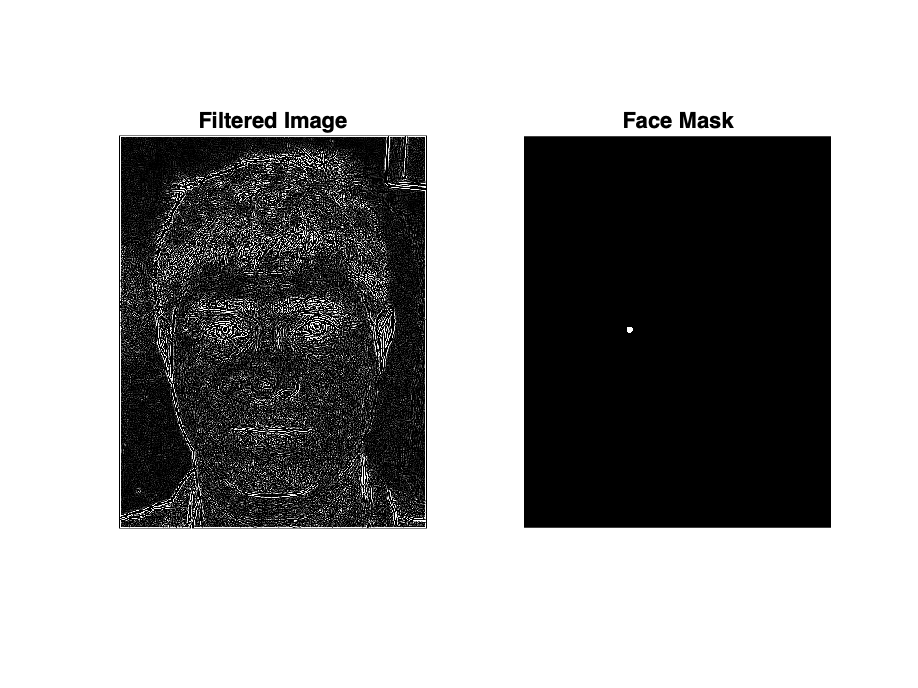

% Lab 2 BOB
image = imread('images/DB1/db1_01.jpg');
image = im2double(image);

sob_x = [-1 -2 -1;
          0  0  0;
          1  2 1 ];

image6 = imfilter(image, sob_x);

sob_y = [-1 0 1;
         -2 0 2;
         -1 0 1];

image7 = imfilter(image, sob_y);

gradientImage = (image6.^2 + image7.^2).^(1/2);
gradientImage = im2gray(gradientImage);


w = fspecial('log',[3 3], 0.5);
filtered_img = imfilter(gradientImage, w, 'replicate');

% Assume 'filtered_img' is the gradient image from your previous code
threshold = graythresh(filtered_img); % Otsu's method to find a threshold
binaryImage = imbinarize(filtered_img, threshold);

% Perform morphological closing to connect edges
se = strel('disk', 1); % Adjust the size as necessary
% binaryImage = imclose(binaryImage, se);

% Fill in the regions
binaryImage = imfill(binaryImage, 'holes');

% Perform morphological opening to remove noise
binaryImage = imopen(binaryImage, se);

% Label connected components
labeledImage = bwlabel(binaryImage);

% Measure properties of labeled regions
regionProps = regionprops(labeledImage, 'Area', 'BoundingBox', 'Solidity');

% Filter out regions that don't meet certain criteria (e.g., area, solidity)
% This is a simplistic filter, you'll need to adjust the parameters
faceRegion = max([regionProps.Area]);
faceMask = ismember(labeledImage, find([regionProps.Area] == faceRegion));

% Display the results
figure;
subplot(1, 2, 1); imshow(filtered_img); title('Filtered Image');
subplot(1, 2, 2); imshow(faceMask); title('Face Mask');

addpath('functions');

% Parameters
numImages = 16;
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 0.90;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = loadAndPreprocessImages(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = performPCA(dataMatrix, commonSize, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

% Project query image onto eigenfaces
queryImagePath = 'images/DB1/db1_01.jpg';
queryWeights = projectOntoEigenfaces(queryImagePath, eigenfaces, meanFace, commonSize);

% Recognize the face
recognizeFace(queryWeights, score, numImages, folderPath, imageFiles, numEigenfaces);